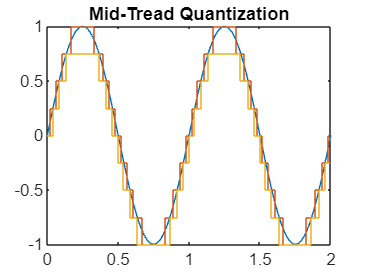

N = 8; 
Delta = 2 / N; 
% Generate a sample analog signal
t = linspace(0, 2, 1000);
analog_signal = sin(2*pi*1*t);

% Quantize the analog signal using mid-rise quantization
quantized_signal_midrise = Delta * floor(analog_signal / Delta + 0.5);
quantized_mid_tread=floor(analog_signal/Delta)*Delta;
% Plot the original and quantized signals
figure;
%subplot(3,1,1);
plot(t, analog_signal);
title('Original Analog Signal');
hold on;

%subplot(3,1,2);
stairs(t, quantized_signal_midrise);
title('Mid-Rise Quantization');

stairs(t, quantized_mid_tread);
title('Mid-Tread Quantization');
hold off;